# 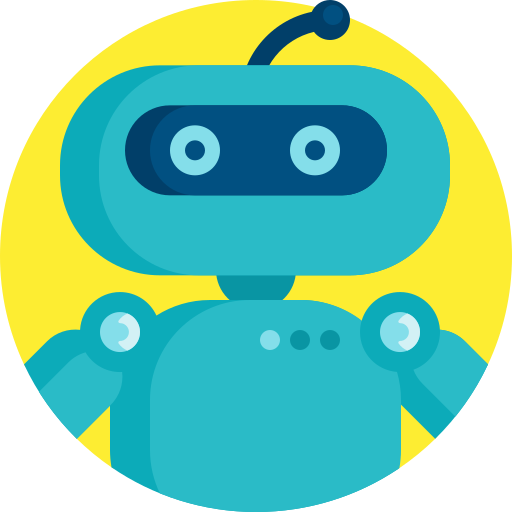

# **MEC4127F: Introduction to Robotics**

# Project — Part 1: Trajectory tracking of a wheeled robot in simulation

## Introduction

You are tasked with making a differentially-steered robot move through arbitrarily specified waypoints within a given time frame, as shown in Figure 1. This will involve the following key milestones:

- **Task 1**: Design an odometry system to estimate robot pose from wheel encoder information;

- **Task 2**: Design a trajectory generator scheme to join the specified waypoints;

- **Task 3**: Design a control scheme so that the robot follows the trajectory and completes the trajectory within the allowed time frame.

The following tasks will first be completed within a software-in-the-loop (SIL) environment, where the robot kinematics and measurements are simulated in Simulink. On completion of the above-mentioned tasks, you will then have a chance to demonstrate that your solution can work on a physical wheeled platform. Physical testing will take place in the final week of term and more information relating to this will be released in the coming days. The Simulink environment has been set up in such a way that you can copy and paste your code blocks from the simulated environment when testing on the physical platform. Note that based on the sim-to-real gap, there may be elements of your design schemes that may need changing to obtain the desired performance.

The content that has been covered thus far in this course should suffice in terms of solving this problem, but you are also welcome to seek solutions outside of the course material. 

The simulation environment is set up in a way that you can solve the above-mentioned tasks in a procedural way, with visual information at hand to help ratify that your approach is sound. Figure 1 shows a visualisation of the robotic platform that will appear every time the Simulink file is run. 

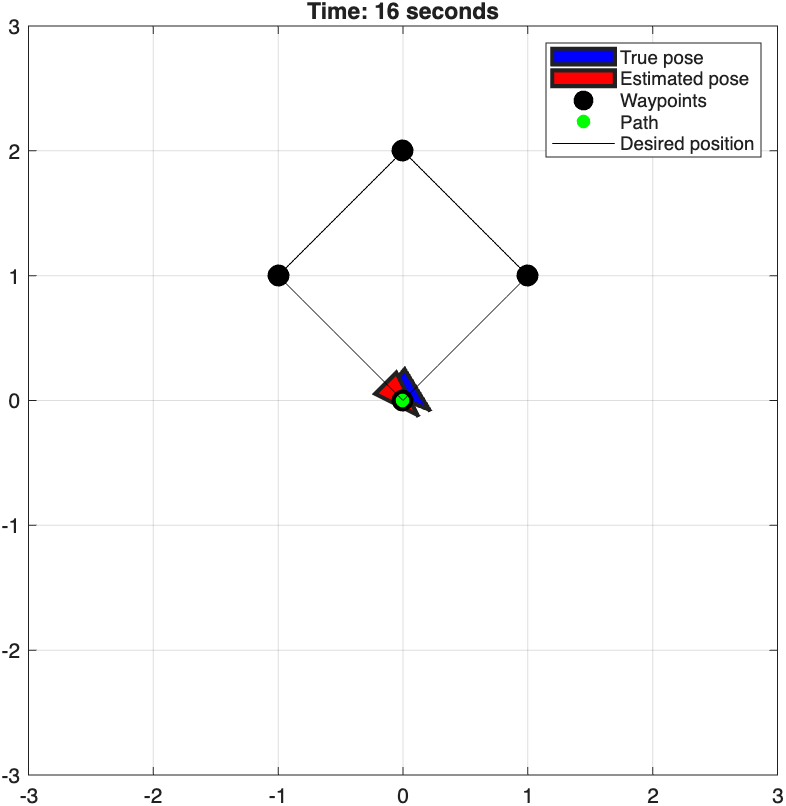

**Figure 1: **Visualisation of simulated robot completing trajectory within 16 seconds.

This will be useful in terms of checking that you are correctly meeting the goals of the project.

## System information

The robot has some important information that will be relevant to you solving the above-mentioned tasks. The notable information is as follows:

- The wheel radii on the robot is approximately given by $r_W=3.38$ cm.

- The wheel centre-to-centre distance is approximately given by $d=10.8$ cm.

- The wheel speed information is accessible at a rate of $f=50$ Hz.

- The wheel speeds have a bi-directional saturation limit of $\dot\phi_{lim}=9.72$ rad/s.

- When viewed from above, motor 1 in the simulation environment is the left wheel and motor 2 is the right wheel.

The above-mentioned information applies to both the simulated robot and the real robot. You are free to alter $r_W$ and $d$ as required when it comes to testing on the physical platform. It is, however, not advisable to do so for the simulated stage of this project.

## Simulation environment

You are provided with a Simulink environment, where you will implement all your work for Part 1 of the Project. The simulation environment contains three main subsystems:

- `Signal Unpacking,`

- `Robot Navigation & Control,`

- `2Wh. Robot`.

You will only be working in the subsystem block called `Robot Navigation & Control `throughout the project. The other subsystems are responsible for routing signal information, simulating motor dynamics, generating ground truth data, and rendering the robot visualisation, but are locked from access. 

When you are ready to simulate the robot, you can click the `Run `button, which is located in the top banner of Simulink. The Simulink file is set to run for 16 seconds, but you can change the Stop Time in the top banner of Simulink, if required. 

Another useful tool to help understand and/or debug your code is the [Data Inspector](https://nl.mathworks.com/help/simulink/slref/simulationdatainspector.html) tool. The tool can be found in the top banner of Simulink, within the SIMULATION tab. The tool works by first right-clicking on a signal in your simulation environment and then selecting *Log Selected Signals*. After you next run your code, you can select and visual the selected signals as they change of the duration of the simulation duration. By default, the ground truth pose signal, `pose_gt`, and estimated pose, `pose_est`, are being logged for use in the Data Inspector tool.

You are also strongly encouraged to use MATLAB to test out ideas and rapidly prototype solutions. Code blocks are given below for sake of convenience. However, note that submission of this live script is not required for this project.

## Task 1: Odometry

The first task will be to use wheel encoder information from the robot to estimate the pose with respect to the world during the simulation. You have access to the simulated wheel velocities of the robot and must use an appropriate estimation scheme to determine a suitably accurate estimate of the robot pose. While **Section 6.3.5** serves as a suitable approach to solve this problem, you are welcome to use other methods. However, top marks will be awarded to the most accurate approach. 

The simulation environment also includes a "ground truth" source for the robot pose, which you can treat as the exact pose of the robot. In the simulation environment this signal is called `pose_gt`. Due to measurement noise and other digital effects, the measurements that you will use to estimate the pose will be imperfect. As such, you should not be surprised if you see that that your estimated pose and the true pose diverge over time. However, in the short term, the two should match very well if your odometry approach is good.

Within `Robot Navigation & Control` subsystem block is another subsystem blocked called `Pose Estimator`, as shown in Figure 2, which is where you will be developing your pose estimation solution for **Task 1**. 

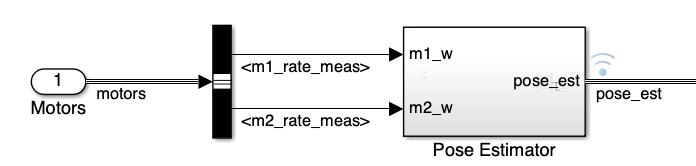

**Figure 2: **`Pose Estimator block` within `Robot Navigation & Control subsystem.`

As shown in the figure above, the `Pose Estimator `block takes in the two motor measurements, which you can use to estimate pose. You can assume that the pose of the robot is initially given by


$$\begin{array}{ll}
{^W{\mathbf T}_B}

= \left[\begin{array}{cc}   1 & 0 & 0 \\     0 & 1 & 0     \\ 0 & 0 & 1 \end{array}\right].
\end{array}$$


You can ignore the `Trajectory Generator `and `Feedback Controller `blocks (for now) — these will be used in the subsequent tasks.

When you run the code for the first time, you will see that a figure similar to Figure 1 will pop up, which shows the following information:

- Time elapsed;

- True pose of the robot (blue);

- Estimated pose of the robot (red);

- Waypoints (black dots);

- Desired position (green dot);

- Path (black line — currently not specified).

With reference to Figure 3, the two wheel commands are initially set to $5$ and $-5$ rad/s, which means that the robot will initially spin around on the spot. The true pose data (blue triangle) will infer this, but the estimated pose will not, as you have not developed the code to do that yet!

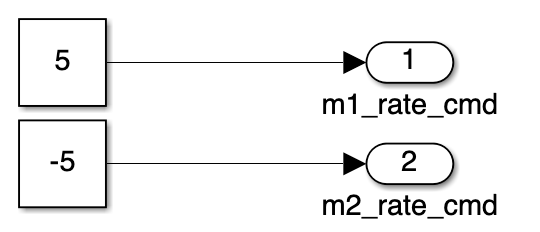

**Figure 3: **Assigning motor rate commands in the `Feedback Controller `block.

The main information for this task is the true pose and estimated pose, as you will use this comparison to ensure that your estimated approach matches that of the true robot behaviour. In order to make the too match sufficiently well, you will need to add the appropriate algorithm in the `Pose Estimator `block. You can either solve the problem using entirely Simulink blocks, or you can also use [MATLAB Function](https://nl.mathworks.com/help/simulink/slref/matlabfunction.html) blocks, which is quite helpful when you cannot find the appropriate Simulink block. Some of the information presented in the System information section will be relevant for this task.

%TASK 1 CODE BLOCK (IF REQUIRED)


When you are ready to test your estimator, you can then try different combinations of wheel speed commands, which is found in the `Feedback Controller `subsystem, with the nominal values shown in Figure 3. If you are happy that the estimated pose (red triangle) is sufficiently well-matched with the true pose (blue triangle) in the visualisation, you can move on to the next task.

## Task 2: Trajectory Generation

With the pose estimation out of the way, the next task is generate an appropriate trajectory that the wheeled robot can follow. In particular, the robot must move through a set number of arbitrarily specified waypoint discs *within 16 seconds*. The nominal waypoints can be found in the `Robot Navigation & Control `subsystem, as shown in Figure 4.

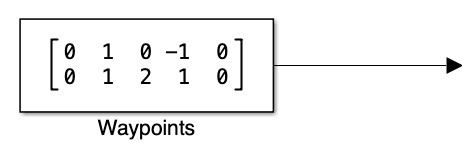

**Figure 4: **Nominal waypoints that will be used to test the trajectory generation scheme.

The waypoints are structured as a $2\times N$ matrix, where the first row corresponds to waypoint information for the x-axis of $\{W\}$, the second row corresponds to waypoint information for the y-axis of $\{W\}$, and $N$ corresponds to the number of waypoints (in the default case $N=5$). Note that the trajectory generation scheme you develop must be generalisable to any combination of waypoints. That is, the above values, or number of waypoints, could change. In other words, you cannot hard code a trajectory generation solution and expect to get full marks for this task.

You can make use of a trajectory generation scheme as detailed in **Chapter 7 **of the notes, or the simpler approach shown in **Section 8.5**. You are also welcome to use a completely different approach that has not been explored in this course. Note, with reference to Figure 1, that the waypoints can be considered as discs rather than points, which gives you some freedom in terms of not having to go exactly through the point, but rather simply being sufficiently close to each waypoint.

As with **Task 1**, you are required to develop your **Task 2** solution using Simulink blocks and/or MATLAB Function blocks, within the `Trajectory Generator `subsystem. It may be easiest to first solve this problem in a MATLAB script, before testing it in the Simulink environment. It is important to make use of the System information in order to correctly space the array.

With reference to Figure 5, `Goto `blocks (for example, the tag with `p_des_array`) are used within the `Trajectory Generator `subsystem to push information to the robot visualiser, which will be useful for validating your approach. 

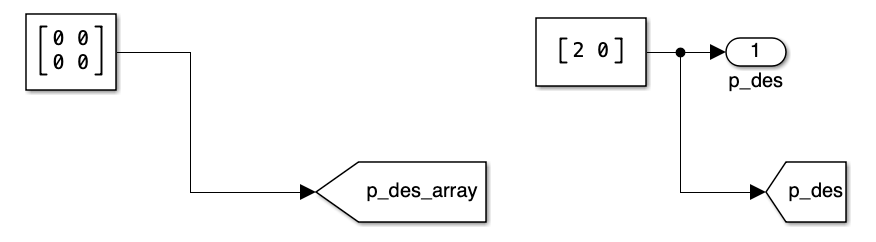

**Figure 5: **`Goto` blocks used to push information to robot visualiser.

As such, you should continue to make use of these tags when you develop your solution in **Task 2** (and **Task 3**). The `p_des_array `Goto tag represents the $2\times M$ desired position array, where the first row corresponds to trajectory information for the x-axis of $\{W\}$, the second row corresponds to trajectory information for the y-axis of $\{W\}$, and $M$ corresponds to the number of points over the entire trajectory. It is important that you maintain this structure. Otherwise, the visualiser will not correctly render the path. Finally, The output of the `Trajectory Generator `subsystem, `p_des`, represents the desired 2D position at the current sampling instance. This signal will also be used by the feedback controller in **Task 3**. This information must be extracted from `p_des_array` using an appropriate method, such as using indexing. Signal `p_des `is also pushed to the robot visualiser and can be used to verify that (a) the point is moving along the correct path, and (b) the point `p_des` completes the trajectory within 16 seconds.

%TASK 2 CODE BLOCK (IF REQUIRED)


When you are happy that the path (black line) and desired position over time (green dot) in the robot visualiser is behaving as expected and satisfying the above-mentioned criteria, you can move on to the next task.

## Task 3: Feedback Control

With the pose estimator and trajectory generator in place, the final task is to design an appropriate feedback controller such that the simulated robot can follow `p_des `along the trajectory, move through each waypoint disc, and complete the trajectory within 16 seconds. All algorithms related to achieving the feedback controller should be housed in the `Feedback Controller `block, as shown in Figure 6.

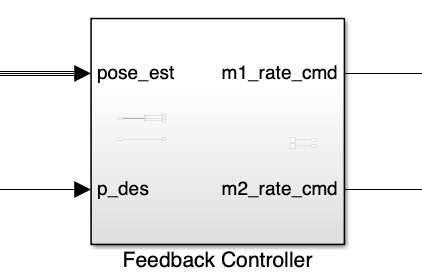

**Figure 6: **`Feedback Controller` subsystem, taking estimated pose and desired position as input, and commanded motor rates as outputs.

The feedback controller must make use of the estimated pose, `pose_est` (from **Task 1**), and the desired position, `p_des` (from **Task 2**), in order to inform how the two motor velocities should change. It is advisable to use the control design approach from **Section 8.5** of the course notes, but you are welcome to use another method too. You are required to implement your control solution in the `Feedback Controller` subsystem, using Simulink blocks and/or `MATLAB Function` blocks. Some useful blocks are the `PID Controller` block, `Transfer Fcn` block, and the `LTI System `block. MATLAB Function blocks may also be useful for reference mappings. It is important to bear in mind the constraints presented in the System information section, as usual.

If the feedback control scheme works effectively, you should see the robot (red triangle) move along the path and keep up with the desired position (green dot). Depending on your design approach, you may need to iteratively adjust the control gains. Note that the control design may also inform an adjustment of your trajectory generation scheme in **Task 2**. For example, it could be that your trajectory is too fast for the robot, based on wheel velocity limits.

%TASK 3 CODE BLOCK (IF REQUIRED)


When you are happy that all elements of your solution are working in unison, you can submit your Simulink file. See details below.

## Submission

Your completed Simulink file must be submitted on Amathuba by the indicated deadline, with your student number appended to the filename. You will be marked entirely within this Simulink environment, so be sure that the file can operate entirely without requiring knowledge of information in the MATLAB workspace. If the Simulink file does not compile, you will receive $0\%$ for the Project. You should still submit your Simulink file even if you have not competed all the tasks, as you can still obtain marks or part marks for the work you have completed.

Marking is based on adhering to the above-mentioned project requirements. As such, it is possible for two fairly different approaches to receive full marks if the end goal of moving through all waypoint discs and completing the trajectory within 16 seconds is achieved. Part marks can still be obtained based on the number of waypoints that the robot reaches, as well as based on the functionality of the pose estimator, trajectory generator, and control scheme.

This concludes Part 1 of the Project. Part 2 will involve implementing your algorithms on the physical platform. More information will be released in the coming days.